X = [-2.1 -2 -1.1 -1 -0.9 -0.2 -0.1 0 0.1 0.9 1 1.1 1.9 2 2.1 3];
y = [1 2 1 2 3 1 2 3 4 2 3 4 3 4 5 5]';

(a) Apply least-squares linear regression to the data to generate a prediction model 

X = [X ; ones(1, length(X))]; 
w = pinv(X')*y;

w_padded = repmat(w,1,16);
y_te_prediction = dot(w_padded, X, 1); 

(b) In a single figure, plot the sixteen data samples and the optimized model as a straight line in the x-y space.

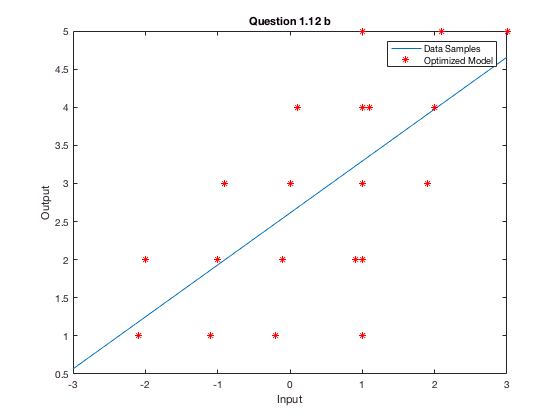

opt_model = zeros(1,length(-3:3));
for i = 1:length(opt_model)
    opt_model(i) = dot(w, [i-4;1], 1);
end 

figure(1) 
plot([-3:3], opt_model)
hold on; 
plot(X, y, '*r')
xlabel('Input') 
ylabel('Output')
legend('Optimized Model', 'Data Samples')
title('Question 1.12 b')

(c) Use the model obtain to predict the output for input x = 1.5. 

prediction = dot(w, [1.5; 1], 1)

prediction =    3.634857885393218